**Configuration**

Add path for DMP and CasADi toolboxes

clear all; clc
casadi_path = "C:\Users\tadas\Dropbox\MATLAB\casadi_win"

casadi_path = "C:\Users\tadas\Dropbox\MATLAB\casadi_win"

%casadi_path = "C:\Users\ge89liz\Dropbox\MATLAB\casadi_win"

% Add paths for DMP, OCP and CasADi dependencies
addpath(genpath('..\libs\DMP'));
addpath(genpath('..\libs\OMF'));
addpath(genpath(casadi_path));

% OCP solver parameters
n_interval = 200;
t_final = 8;

% Integration time-step for reconstructing DMP
dt = 0.001;

% Define control-affine system of the form
% x' = f(x) + g(x)u  (1)
%
% NOTE: It is assumed that 'u' can be recovered from (1)    
%
f = @(x) [-x(1)^2; -2*x(2)];
g = @(x) [1 x(1); 0 1];
F = @(x,u) f(x) + g(x)*u;
reverse_F = @(x,u) -f(x) - g(x)*u;

% Integrand of cost function
I = @(u) vecnorm(u').^2;

% Control input as a function of the state and its derivative
u_fcn_x_dx = @(x, dx) inv(g(x))*(dx - f(x));

n_states = 2;
n_inputs = 2;

% Choose DMP type:
% 1: Vanilla DMP proposed by Ijspeert et al. 2002
% 2: DMP using the time-varying stiffness modification proposed by Weitschat et al.
DMP.type = 1;

**Sampling based on co-state and optimal value approximation**

Generate solutions for the parametrized optimal control problem

minimize $\int_{t_0}^{t_f}  \| u(s) \|^{2} ds$

s.t. $\dot{x} = F(x,u) = f(x) + g(x)u(x)$

      
$$x(t_0) = x_0$$


      
$$x(t_f) = x_1$$


where $x_1 \in \mathbb{P}$.

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1604
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     1200

Total number of variables............................:      802
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

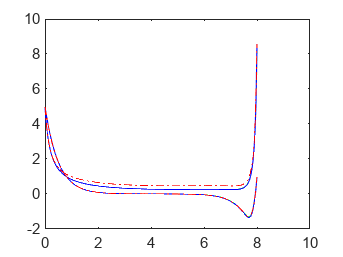

% x_final will be moving while x_initial is kept constant
x_initial = [5; 5];
x_final = [1; 1];  
N_samples = 15;
x_step = 0.2; % Spatial increment
max_step = 5; % Number of steps before forcing taking another sample
threshold = 10;

samples = {};
samples{1} = x_final;
n = 1;
x_direction = [1; 0];

% Initialize data for plotting
x_values = [];
optimal_costs = [];
estimated_costs = [];
DMP_costs = [];

% Start sampling algorithm
while n <= N_samples    

    x_values = [x_values x_final];

    % Sample backward solution from numerical solver 
    % Note: must transpose u_training and x_training before using with
    % other functions
    [time_training, u_training, x_training] = solve_OCP_direct_method( ...
                reverse_F, ...    % System dynamics x' = F(x,u)
                n_states,   ...   % Number of states of system
                n_inputs,   ...   % Number of inputs of system
                n_interval, ...   % Number of control intervals
                [0 t_final], ...  % Time horizon
                x_final, ...      % Initial state
                x_initial);       % Terminal state

    % Pre-process optimal trajectory and encode in DMP
    trj = zeros(n_interval+1, n_states);
    for j=1:n_states
        for k=1:n_interval+1
            trj(k,j) = x_training(j,n_interval+2-k);
        end
    end   
    DMP.N = 80;
    if DMP.type == 1
        DMP = DMP_train(trj, time_training, DMP);
    elseif DMP.type == 2
        DMP = OMF_train(trj, time_training, DMP);
    end
    learned_DMP = DMP;           
    
    % Transpose the solution to use with auxilary functions
    u_training = u_training';
    x_training = x_training';
    
    % Co-state trajectory and optimal cost 
    p_training = compute_costate_rev(x_training(1:end-1,:), u_training, g); % must has the same size as u_training
    cost_training = compute_cost(u_training, time_training(1:end-1));    

    % Record costs at new sampling point
    optimal_costs = [optimal_costs cost_training];
    estimated_costs = [estimated_costs cost_training];
    DMP_costs = [DMP_costs cost_training];

    % Test DMPs in a h-neighborhood of sampled solution    
    n_step = 1;
    while 1    
        h = n_step*x_step;
        % Compute a first-order approximation of optimal cost in x direction
        estimated_V = cost_training + h*(p_training(1,:)*x_direction);
    
        % Compute DMP in this direction
        next_x = x_final + h*x_direction;
        x_values = [x_values next_x];
        estimated_costs = [estimated_costs estimated_V];
        learned_DMP.goal = next_x;
        [x_DMP, time_DMP] = DMP_trajectory(learned_DMP, dt, t_final);
        u_DMP = DMP_compute_input(x_DMP, time_DMP, u_fcn_x_dx);

        DMP_cost = compute_cost(u_DMP', time_DMP);
        DMP_costs = [DMP_costs DMP_cost];

        % Compute cost of numerical solution for comparison
        [time_gt, u_gt, x_gt] = solve_OCP_direct_method( ...
                F, ...            % System dynamics x' = F(x,u)
                n_states,   ...   % Number of states of system
                n_inputs,   ...   % Number of inputs of system
                n_interval, ...   % Number of control intervals
                [0 t_final], ...  % Time horizon
                x_initial, ...    % Initial state
                next_x);         % Terminal state

        cost_gt = compute_cost(u_gt', time_gt(1:end-1));
        optimal_costs = [optimal_costs cost_gt];

        % Plot input of DMP
        %plot(time_gt(1:end-1), u_gt, 'b-', ...
        %     time_DMP, u_DMP, 'r-.')

        % Plot DMP approximation for optimal trajectory
        plot(time_training, flipud(x_training), 'g', ...
             time_gt, x_gt, 'b-', ...
             time_DMP, x_DMP, 'r-.')
    
        % Compare DMP cost with estimated optimal cost
        % If the difference is higher than a threshold prepare new sample, otherwise ignore
        % Also break the loop if the n_step has surpassed certain limit
        % because then the optimal cost estimator will lose too much precision
        if (abs(DMP_cost - estimated_V) >= threshold) || (n_step > max_step)
            % Record sample
            samples{n+1} = next_x;
            % Next iteration
            x_final = next_x;
            n = n + 1;
            break;
        end
        n_step = n_step + 1;
    end
end

**Visualization of results**

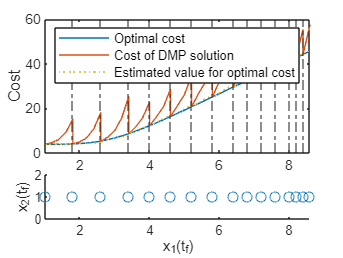

% figure;
% Convert sampling points to matrix
m_samples = cell2mat(samples);


% Compare cost of optimal solution with cost of DMP solution
subplot(3,1,1:2)
plot(x_values(1,:), optimal_costs, ...
     x_values(1,:), DMP_costs, ...
     x_values(1,:), estimated_costs, ':');

xline(m_samples(1,:),'-.');
legend('Optimal cost', 'Cost of DMP solution', 'Estimated value for optimal cost', 'Location', 'northwest');

ylabel('Cost');
xlim([1,max(m_samples(1,:))])

% Sampling grid 
subplot(3,1,3)
scatter(m_samples(1,:), m_samples(2,:));
% title('Sampling grid');
xlabel('x_1(t_f)');
ylabel('x_2(t_f)');
xlim([1,max(m_samples(1,:))])


% Metrics
max_error = max(abs(optimal_costs - estimated_costs))

max_error = 1.0783

max_relative_error = max(abs(optimal_costs - estimated_costs)./optimal_costs) * 100

max_relative_error = 14.6980

min_diff_sample = min(diff(m_samples(1,:)))

min_diff_sample = 0.2000

total_samples_uniform = ceil((max(m_samples(1,:)) - 1) / min_diff_sample)

total_samples_uniform = 39


save('data/sampling_plots.mat')

**Auxiliary functions**

**Solve OCP by direct method using RK4 integration**

function [t,u,x] = solve_OCP_direct_method(F, n_states, n_inputs, N, time_range, x0, x1)
    opti = casadi.Opti(); % Optimization problem

    % Solver config
    solver_options= struct;
    solver_options.ipopt.print_level = 0;
    solver_options.print_time =0;
    solver_options.verbose = 0;
    
    % ---- decision variables ---------
    X = opti.variable(n_states,N+1); % state trajectory
    U = opti.variable(n_inputs,N);   % control trajectory 
    ti = time_range(1);       
    tf = time_range(2);       
    T = tf - ti;              % time horizon 
    
    % ---- objective          ---------
    opti.minimize(dot(U,U)); 
        
    dt = T/N; % length of a control interval
    for k=1:N % loop over control intervals
        % Runge-Kutta 4 integration
        k1 = F(X(:,k),         U(:,k));
        k2 = F(X(:,k)+dt/2*k1, U(:,k));
        k3 = F(X(:,k)+dt/2*k2, U(:,k));
        k4 = F(X(:,k)+dt*k3,   U(:,k));
        x_next = X(:,k) + dt/6*(k1+2*k2+2*k3+k4); 
        opti.subject_to(X(:,k+1)==x_next); % close the gaps
    end
    
    % ---- boundary conditions --------
    opti.subject_to(X(:, 1)==x0);
    opti.subject_to(X(:, end)==x1);      
    
    %% Initial values
    opti.set_initial(X, zeros(n_states,N+1));
    opti.set_initial(U, ones(n_inputs,N));
    
    % ---- solve NLP              ------
    opti.solver('ipopt'); % set numerical backend
    sol = opti.solve();   % actual solve    
    
    x = sol.value(X);
    u = sol.value(U);
    t = linspace(0,sol.value(T),N+1);    
end


**Reconstruct DMP** 

function [TRJ, TT] = DMP_trajectory(DMP, dt, t_end)
    % initialize the DMP state
    S.x = 1; 
    S.y = DMP.y0; 
    S.z = DMP.dy0*DMP.tau;
    S.t = 0;
    t = 0;
    TRJ = [S.y]; TT = [t]; TRJD = [DMP.dy0];
    % reconstruct the trajectory by Euler integration (F times higher than
    % the trajectory sampling rate)
    F = 1;
    dt = dt / F;
    while t < t_end
        for i = 1:F
            if DMP.type == 1
                S = DMP_integrate(DMP, S, dt);
            elseif DMP_type == 2
                S = OMF_integrate(DMP, S, dt);
            end
            t = t + dt;
        end
        TT = [TT; t];
        TRJ = [TRJ; S.y];
    end
end


**Compute control input associated to DMP**

Assumes that *u* can be expressed as a function $$u = u(x,\dot{x})$
$

function u_DMP = DMP_compute_input(x_DMP, time, u_fcn_x_dx)
    n_states = size(x_DMP, 2);
    n_samples = length(time);

    u_DMP = {};
    % Compute x'_DMP using numerical derivative
    dx_DMP= [gradient(x_DMP(:,1), time) ...
             gradient(x_DMP(:,2), time)];
    
    % Recover control input from DMP
    for t=1:n_samples
        u_DMP{t} = u_fcn_x_dx(x_DMP(t,:)', dx_DMP(t,:)');
    end
    u_DMP = cell2mat(u_DMP);
end

**Compute Hamiltonian**

The Hamiltonian is defined as 


$$H(x,u,p) = p^Tf(x,u) + I(x,u)$$


**Note**: some references define the Hamiltonian as 


$$H(x,u,p) = - p^Tf(x,u) + I(x,u)$$


and the co-state becomes the negative of the co-state defined by the first equation.

function H = compute_Hamiltonian(x, u, p, F, I)
    H = zeros(1,length(x)-1);
    for t=1:length(x)-1
        H(t) = p(t,:)*F(x(t,:)',u(t,:)') - I(u(t,:));
    end    
end


**Compute evolution of co-state (p)**

By Bellman's optimality principle the optimal value function (V)  is related to the optimal cost (u*) by


$$u^*(x,t) = -\frac{1}{2}R^{-1}g^{T}(x)\frac{\partial{V}}{\partial{x}} (x,t)$$


In other words,


$$\frac{\partial V}{\partial x}(x,t) = -2 g^{-T}(x) R u^{*}(x,t)$$


Assuming that $V$ is first differentiable w.r.t time and state, 


$$p(x,t) = \frac{\partial V}{\partial x}(x,t)$$


function p = compute_costate(x, u, g)
    dVdX = -2*g(x)*u';
    p = dVdX;
    p = p';
end

**Compute evolution of co-state of the reverse system**

Here we compute the co-state of the reverse system 


$$\dot{x} = -f(x) - g(x)u(x)$$
 

**Note**: we created another function because MATLAB does not accept to pass $-g$ as an argument to `compute_costate`

function p = compute_costate_rev(x, u, g)
   dVdX = zeros(size(u));
   for t = 1:size(x, 1) % samples
        dVdX(t,:) = 2*inv(g(x(t,:)))'*u(t,:)';
   end
   p = dVdX;
   %p = p';
end

**Compute total cost**

The total cost is given by 


$$J(u)=\int_{0}^{t_f} I(x(s),u(s)) \, ds $$


where


$$I(x,u) = \| u \|^2 $$


function cost = compute_cost(u, time)
    if(size(u,2) ~= 2)
        disp('Warning: check if u argument is being passed right')
    end
    cost = trapz(time, vecnorm(u,2,2).^2);
end

**Computes solution of linear OCP**

Generates the solution of the optimal control problem


$$$\min \int_{0}^{t_f} \| u(s)\|^2\,ds$$


subject to 


$$\dot{x}(t) = Ax(t) + Bu(t)$$



$$x(0)= x_0$$



$$x(t_f) = x_1$$


% Generates optimal control problem
function [u,x,t,cost] = analytic_solution(A,B,x0,x1,T,dt)
    syms t v
    
    W = int(expm(A*t)*(B*B')*expm(A'*t),[0,T]);
    % Check condition number for debug:
    % cond(vpa(W))
    z = -B'*expm(A'*(T-t))/W;
    
    % u(t) = -B'*e^[A(T-t)]*inv(W)*(e^[AT]*x0 - x1)
    u = z*(expm(A*T)*x0 - x1);
    
    f = int( expm(A*(t-v))*B*subs(u,t,v) , v, 0, t);
    
    % x'(t) = Ax(t) + f(t)
    x = matlabFunction(expm(A*t)*x0 + f);
    u = matlabFunction(u);
    
    cost = vpa((expm(A*T)*x0 - x1)'*inv(W')*(expm(A*T)*x0 - x1));
    
    t = 0:dt:T;
    x = x(t);
    u = u(t);
end 